Load images into the "imageDatastore" variable.

signalDatasetPath = fullfile('signals');
imds = imageDatastore(signalDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

Show a couple of images to check if the data is correct.

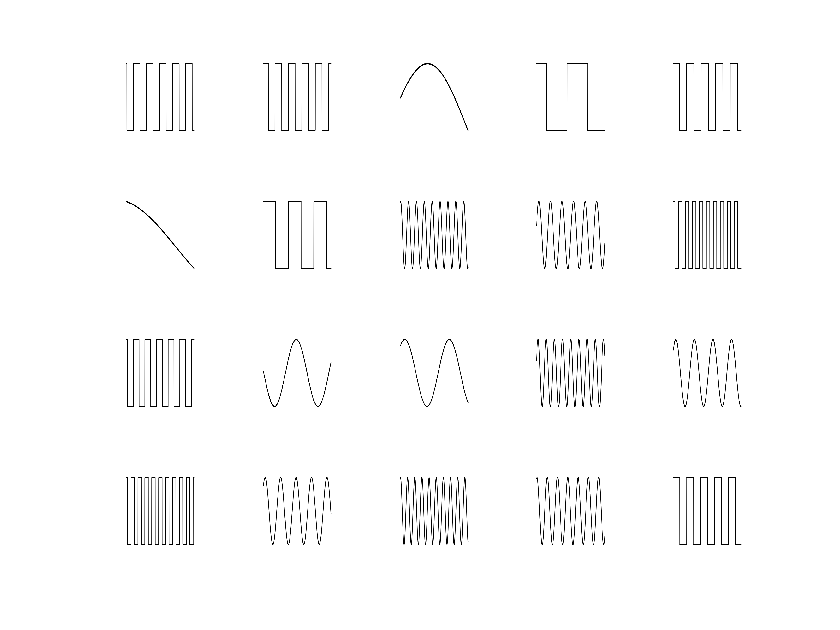

figure;
perm = randperm(200,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

Show the number of items for each label in the dataset.

labelCount = countEachLabel(imds)

labelCount = 2×2 table
    Label    Count
    _____    _____

     bin      100 
     sin      100 


Check the size of each image.

for i = 1:200
img = readimage(imds,i);
if size(img) ~= 400
    size(img)
    i
end
end

Split the dataset in two parts - for the training and validation respectively.

numTrainFiles = 75;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

Create layers for our deep learning network.

layers = [
    % An imageInputLayer is where you specify
    %   the image size, which, in this case, is 28-by-28-by-1. 
    % These numbers correspond to the height, width, and the channel size.
    imageInputLayer([400 400 1])
    
    % A 2-D convolutional layer applies sliding convolutional 
    %   filters to the input. 
    % The layer convolves the input by moving the filters 
    %   along the input vertically and horizontally and 
    %   computing the dot product of the weights and the input, 
    %   and then adding a bias term.
    convolution2dLayer(3,8,'Padding','same')
    
    % A batch normalization layer normalizes each input channel 
    %   across a mini-batch.
    batchNormalizationLayer
    
    % A ReLU layer performs a threshold operation to each element 
    %   of the input, where any value less than zero is set to zero.
    reluLayer
    
    % Convolutional layers (with activation functions) are sometimes 
    %   followed by a down-sampling operation that reduces the spatial 
    %   size of the feature map and removes redundant spatial information.
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    % The convolutional and down-sampling layers are followed by 
    %   one or more fully connected layers. 
    % As its name suggests, a fully connected layer is a layer 
    %   in which the neurons connect to all the neurons in the preceding layer. 
    % This layer combines all the features learned by the previous layers 
    %   across the image to identify the larger patterns.
    fullyConnectedLayer(2)
    
    % The softmax activation function normalizes the output 
    %   of the fully connected layer.
    softmaxLayer
    
    % This layer uses the probabilities returned by the softmax 
    %   activation function for each input to assign the input 
    %   to one of the mutually exclusive classes and compute the loss.
    classificationLayer];

Adjust the training otions for the best performance.

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',15, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',10, ...
    'Verbose',false, ...
    'Plots','training-progress');

Train the network.

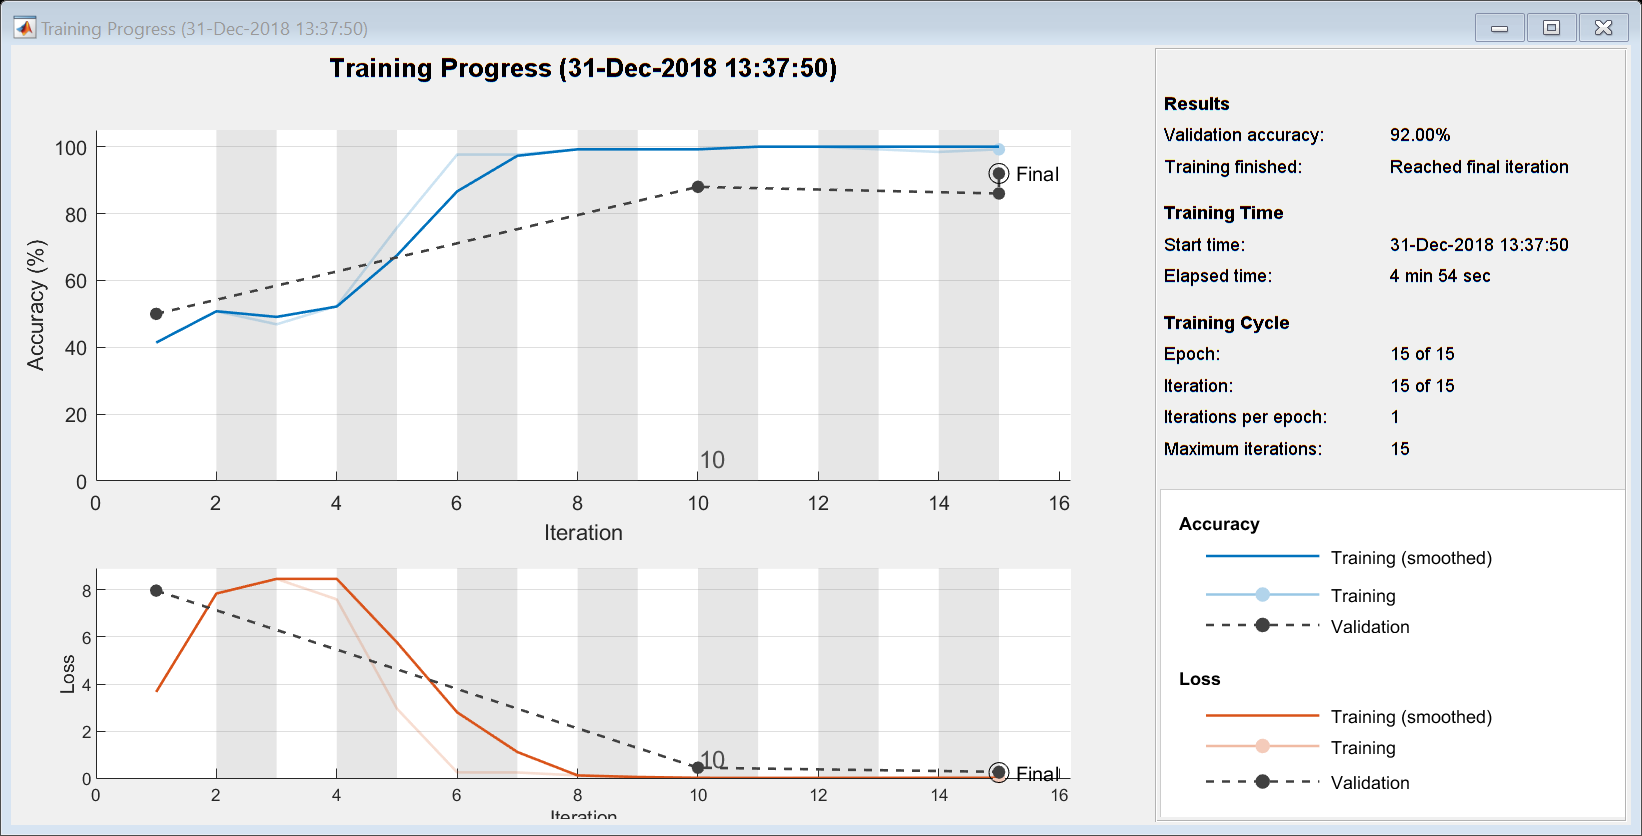

net = trainNetwork(imdsTrain,layers,options);

Make predictions on the validation dataset and calculate loss.

YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.9200

inputSize = net.Layers(1).InputSize(1:2)

inputSize =    400   400


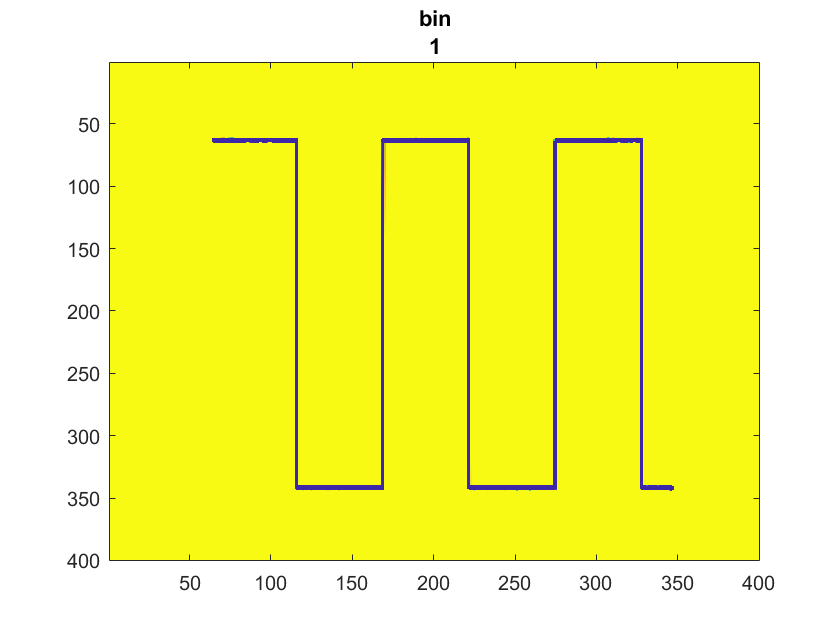

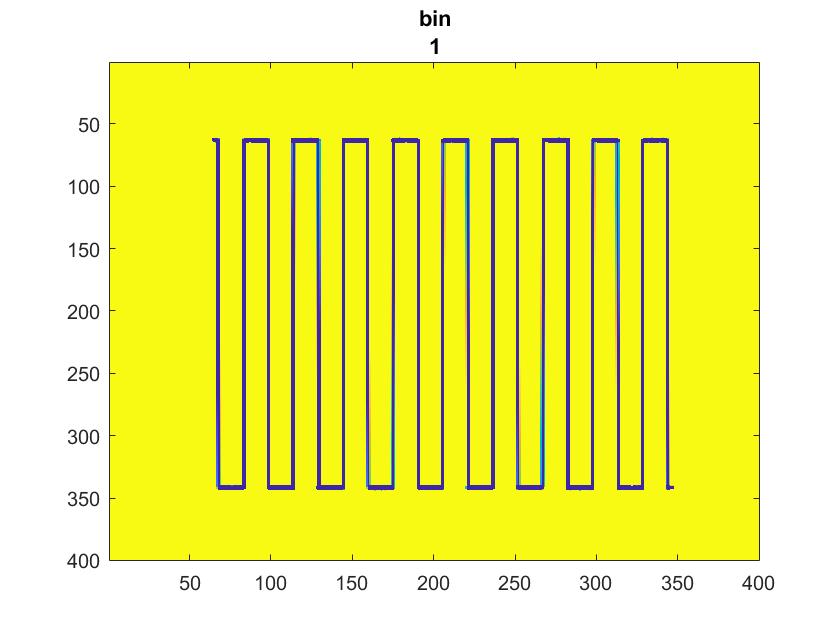

Error using matlab.io.datastore.ImageDatastore/readimage (line 32)
Expected input number 2, INDEX, to be a scalar with value <= 50.

h = figure;
counter = 1;
while ishandle(h)
    im = readimage(imdsValidation, counter);
    counter = counter + 1;
    pause(1);
    image(im)
    [label,score] = classify(net,im);
    title({char(label), num2str(max(score),2)});
    drawnow
end